## **PCE model for sallen key surrogate model fitting**

### **Sample from sallen key**


N_samples = 20000;

R1_nominal = 30e3;
R1_min = 0.95 * R1_nominal;
R1_max = 1.05 * R1_nominal;

R2_nominal = 18e3;
R2_min = 0.95 * R2_nominal;
R2_max = 1.05 * R2_nominal;

C1_nominal = 0.01e-6;
C1_min = 0.95 * C1_nominal;
C1_max = 1.05 * C1_nominal;

C2_nominal = 0.0047e-6;
C2_min = 0.95 * C2_nominal;
C2_max = 1.05 * C2_nominal;

R1_samples = unifrnd(R1_min, R1_max, [N_samples, 1]);
R2_samples = unifrnd(R2_min, R2_max, [N_samples, 1]);
C1_samples = unifrnd(C1_min, C1_max, [N_samples, 1]);
C2_samples = unifrnd(C2_min, C2_max, [N_samples, 1]);

Vout = zeros(N_samples, 1);

for i = 1:N_samples
    Vout(i) = simulate_sallenKeyFilter(R1_samples(i), R2_samples(i), C1_samples(i), C2_samples(i));
end

Vout = abs(Vout) % we only care about the magnitude

Vout =     0.6895
    0.6827
    0.7172
    0.6872
    0.7016
    0.6776
    0.7005
    0.6959
    0.7330
    0.6791


### Normalize to [-1, 1] - range for Legendre domain


function X_norm = normalize_to_legendre(X, X_min, X_max)
    X_norm = 2 * (X - X_min) ./ (X_max - X_min) - 1;
end

R1_samples_norm = normalize_to_legendre(R1_samples, R1_min, R1_max);
R2_samples_norm = normalize_to_legendre(R2_samples, R2_min, R2_max);
C1_samples_norm = normalize_to_legendre(C1_samples, C1_min, C1_max);
C2_samples_norm = normalize_to_legendre(C2_samples, C2_min, C2_max);

X_norm = [R1_samples_norm, R2_samples_norm, C1_samples_norm, C2_samples_norm]; % (N, 4)

X_train = X_norm(1:10000, :);
X_test = X_norm(10001:end, :);

y_train = Vout(1:10000);
y_test = Vout(10001:end, :);

### Create PCE model

#### First, generate multi-indices for all interaction terms and polynomial orders

function alpha = generate_multi_indices(d, p)
    alpha = [];
    for total = 0:p
        temp = nchoosek(repmat(0:total, 1, d), d);
        temp = unique(temp(sum(temp, 2) == total, :), 'rows');
        alpha = [alpha; temp];
    end
end

d = size(X_norm, 2); % number of parameters in our circuit
p = 3; % max Legendre polynomial order

alpha = generate_multi_indices(d, p)

alpha =      0     0     0     0
     0     0     0     1
     0     0     1     0
     0     1     0     0
     1     0     0     0
     0     0     0     2
     0     0     1     1
     0     0     2     0
     0     1     0     1
     0     1     1     0


#### Then, we create a function to evaluate the Legendre polynomials. Technically we could use something like Rodrigue's method to evaluate them, but since we won't really ever use p > 3, we can just write down the first 4 Legendre basis functions and evaluate them directly.

function P = eval_legendre(n, x)
    
    psi = {
        @(x) ones(size(x));         % Psi_0 = 1
        @(x) x;                     % Psi_1 = x
        @(x) 0.5 * (3*x.^2 - 1);    % Psi_2 = 1/2 * (3x^2 - 1)
        @(x) 0.5 * (5*x.^3 - 3*x);  % Psi_3 = 1/2 * (5x^3 - 3x)
    };

    if n < 0 || n > 3
        error('Not currently in range... Add more terms to the hardcoded basis');
    end

    P = psi{n+1}(x);
end

eval_legendre(0, X_norm(:, 1))

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


#### Now we can create the basis matrix which will contain the value of all the Legendre basis functions for each sample. This matrix can then be used with least squares to find the coefficients for best fit.

function Psi = eval_basis_matrix(X, alpha)

    [N, d] = size(X); % N the number of samples and d, the dimensionality - the number of parameters
    P = size(alpha, 1); % number of basis functions (function of the max order of polynomial and number of interaction term given by number of parameters)

    Psi = ones(N, P); % for each sample, the value of all the basis functions evaluated at that sample. The surrogate model is a linear combination of these terms.

    for i = 1:P
        tmp_psi = ones(N, 1);
        for j = 1:d % for each parameter (allows for interaction terms)
            tmp_psi = tmp_psi .* eval_legendre(alpha(i, j), X(:, j));
        end
        Psi(:, i) = tmp_psi;
    end
end

Psi_train = eval_basis_matrix(X_train, alpha)

Psi_train =     1.0000    0.0853   -0.1641    0.4720    0.3069   -0.4891   -0.0140   -0.4596    0.0403   -0.0774   -0.1659    0.0262   -0.0504    0.1449   -0.3587   -0.1265    0.0803   -0.0392    0.2351   -0.2308   -0.0066   -0.2169   -0.0142    0.0272   -0.4451   -0.1501   -0.0043   -0.1411    0.0124   -0.0238   -0.0509   -0.0306    0.0589   -0.1693   -0.3881
    1.0000    0.7517    0.2957    0.0246   -0.1627    0.3476    0.2223   -0.3689    0.0185    0.0073   -0.4991   -0.1223   -0.0481   -0.0040   -0.4603   -0.0656    0.1028   -0.2773   -0.3789    0.0086    0.0055   -0.0091   -0.3752   -0.1476   -0.0369   -0.0566   -0.0362    0.0600   -0.0030   -0.0012    0.0812   -0.3460   -0.1361   -0.0113    0.2333
    1.0000   -0.6242    0.0843   -0.0322    0.5090    0.0844   -0.0526   -0.4893    0.0201   -0.0027   -0.4984   -0.3177    0.0429   -0.0164   -0.1114    0.3284    0.0071    0.3054   -0.1249   -0.0027    0.0017    0.0157    0.3111   -0.0420    0.0482    0.0429   -0.0268   -0.2491    0.

Psi_test = eval_basis_matrix(X_test, alpha)

Psi_test =     1.0000   -0.3422    0.4304   -0.8893    0.7147   -0.3244   -0.1473   -0.2221    0.3043   -0.3828    0.6863   -0.2446    0.3076   -0.6356    0.2662    0.4131   -0.1396    0.0760   -0.4463    0.2885    0.1310    0.1975   -0.2348    0.2954   -0.4244   -0.2318   -0.1053   -0.1587    0.2175   -0.2736    0.4905   -0.0911    0.1146   -0.2367   -0.1594
    1.0000    0.1489   -0.3395   -0.9621   -0.3807   -0.4668   -0.0505   -0.3271   -0.1432    0.3267    0.8884   -0.0567    0.1293    0.3663   -0.2826   -0.2151    0.1585   -0.0487    0.4114    0.4491    0.0486    0.3147    0.1323   -0.3016   -0.7831    0.1777    0.0192    0.1245    0.0545   -0.1244   -0.3382   -0.0421    0.0960    0.2719    0.4331
    1.0000    0.3814    0.7710   -0.0944   -0.2290   -0.2818    0.2941    0.3916   -0.0360   -0.0728   -0.4866   -0.0874   -0.1766    0.0216   -0.4213   -0.4334   -0.2172    0.1494   -0.0108    0.0266   -0.0278   -0.0370   -0.1856   -0.3752    0.1395    0.0645   -0.0674   -0.0897    0.0

#### Now that we have the matrix Psi with all the values of the basis functions, we want to find a linear combination that approximates Vout as well as possible. We will use least squares to do that.

For least squares, we would find the coefficients by doing 

$a={\left(\Psi^T \Psi \right)}^{-1} \Psi^T y$, which would be equivalent to using the matlab built-in \ operator.

% fit the surrogate model 
a = Psi_train \ y_train

a =     0.7058
   -0.0353
    0.0000
   -0.0132
   -0.0220
    0.0009
   -0.0009
   -0.0003
   -0.0002
   -0.0009


a = inv(Psi_train' * Psi_train) * (Psi_train' * y_train)

a =     0.7058
   -0.0353
    0.0000
   -0.0132
   -0.0220
    0.0009
   -0.0009
   -0.0003
   -0.0002
   -0.0009



y_hat_train = Psi_train * a;
mean_res_err_train = mean(abs(y_train - y_hat_train))

mean_res_err_train = 1.4958e-06

rel_err_train = 100 * norm(y_train - y_hat_train) / norm(y_train)

rel_err_train = 3.3082e-04

### Evaluate PCE model

#### Errors and PDFs

y_hat_test = Psi_test * a;
mean_res_err_test = mean(abs(y_test - y_hat_test))

mean_res_err_test = 1.5056e-06

rel_err_test = 100 * norm(y_test - y_hat_test) / norm(y_test)

rel_err_test = 3.2740e-04

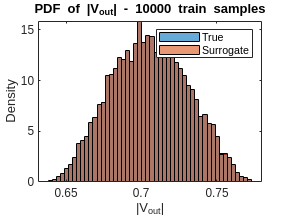


% plot pdf of monte carlo vs surrogate
figure;
histogram(y_test, 50, 'Normalization', 'pdf');
hold on;
histogram(y_hat_test, 50, 'Normalization', 'pdf');
legend('True', 'Surrogate');
title('PDF of |V_{out}| - 10000 train samples');
xlabel('|V_{out}|');
ylabel('Density');

#### Plot error in mean and std predictions over training set size.

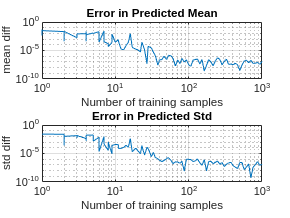

function [mean_errors, std_errors] = mean_std_err_over_train_size(X_all, y_all, alpha, X_test, y_test, sample_sizes)
    
    n_sizes = length(sample_sizes);
    mean_errors = zeros(n_sizes, 1);
    std_errors = zeros(n_sizes, 1);

    Psi_test = eval_basis_matrix(X_test, alpha); % precompute test basis matrix (doesn't change)

    for k = 1:n_sizes
        n_train = sample_sizes(k);

        % select random subset
        idx = randperm(size(X_all, 1), n_train);
        X_train = X_all(idx, :);
        y_train = y_all(idx);

        % get basis matrix for train set
        Psi_train = eval_basis_matrix(X_train, alpha);

        a = Psi_train \ y_train;
        y_hat_test = Psi_test * a;

        % get errors
        mean_errors(k) = abs(mean(y_hat_test) - mean(y_test));
        std_errors(k)  = abs(std(y_hat_test) - std(y_test));
    end
end

sample_sizes = round(logspace(log10(1), log10(1000), 100)); % 1000 samples from 1, to 1000
[mean_errors, std_errors] = mean_std_err_over_train_size(X_train, y_train, alpha, X_test, y_test, sample_sizes);

% plot results
figure

subplot(2,1,1);
loglog(sample_sizes, mean_errors);
title('Error in Predicted Mean');
xlabel('Number of training samples');
ylabel('mean diff');
grid on;

subplot(2,1,2);
loglog(sample_sizes, std_errors);
title('Error in Predicted Std');
xlabel('Number of training samples');
ylabel('std diff');
grid on;

#### Plot PDF with surrogate trained on "only" 100 samples

% fit the surrogate model 
a = Psi_train(1:20, :) \ y_train(1:20)

a =     0.7055
   -0.0352
   -0.0000
   -0.0133
   -0.0222
    0.0007
   -0.0004
   -0.0005
   -0.0012
         0



y_hat_train = Psi_train * a;
mean_res_err_train = mean(abs(y_train - y_hat_train))

mean_res_err_train = 4.6504e-04

rel_err_train = 100 * norm(y_train - y_hat_train) / norm(y_train)

rel_err_train = 0.1018


y_hat_test = Psi_test * a;
mean_res_err_test = mean(abs(y_test - y_hat_test))

mean_res_err_test = 4.6595e-04

rel_err_test = 100 * norm(y_test - y_hat_test) / norm(y_test)

rel_err_test = 0.1018

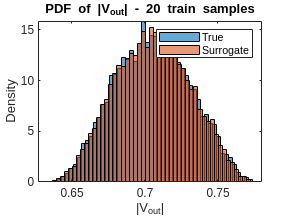


% plot pdf of monte carlo vs surrogate
figure;
histogram(y_test, 50, 'Normalization', 'pdf');
hold on;
histogram(y_hat_test, 50, 'Normalization', 'pdf');
legend('True', 'Surrogate');
title('PDF of |V_{out}| - 20 train samples');
xlabel('|V_{out}|');
ylabel('Density');